# Figure 7

Potential temperature (θ) profile combining the radiosonde launched by SAIL at Gothic 18 April 2023 23:29 UTC (17:29 local) (yellow); the 20 m SOS/NCAR tower at Kettle Ponds (averaged for ±20 min surrounding the radiosonde launch time) (blue line); and the temperature string profile recorded ~5 hours prior to the radiosonde at AYP (red); and the SPLASH ~ 2 m air temperature at KPA (blue dot). The lowest horizontal dashed line is approximately the snow surface height relative to the soil surface; 1000 m is the approximate height of the ridgeline above the surface; and the line near 3 km represents the cloud base height at the time of the radiosounding. All heights are relative to the snow surface and the pressure coordinate for θ is from the lowest height of the tower.

## Prerequisites & data load

Data sources here include the SAIL M1 radiosondes (Keeler et al., 2021), SAIL M1 ceilometer (Zhang et al., 2021), ASFS 30 & 50 (Cox et al. 2023a, b), the SOS 20 m tower (NCAR, 2024), the ASFS 50 thermistor string (Cox et al., 2023c).

Cox, C. J., Gallagher, M., Intrieri, J., Butterworth, B., Meyers, T., & Persson, O. (2023a). Atmospheric Surface Flux Station #30 measurements (level 2 Processed), Study of Precipitation, the Lower Atmosphere and Surface for Hydrometeorology (SPLASH), October 2021-June 2023 [Dataset]. Zenodo. [https://doi.org/10.5281/zenodo.10313895](https://doi.org/10.5281/zenodo.10313895)

Cox, C. J., Gallagher, M., Intrieri, J., Butterworth, B., Meyers, T., & Persson, O. (2023b). Atmospheric Surface Flux Station #50 measurements (level 2 Processed), Study of Precipitation, the Lower Atmosphere and Surface for Hydrometeorology (SPLASH), October 2021-June 2023 [Dataset]. Zenodo. [https://doi.org/10.5281/zenodo.103133364](https://doi.org/10.5281/zenodo.103133364) 

Cox, C. J., Gallagher, M., Intrieri, J., Shupe, M., & Schmatz, B. (2023c). Continuous snow temperature profiles from the Snow Ice Mass Balance Apparatus (SIMBA) (level 1 raw), Study of Precipitation, the Lower Atmosphere and Surface for Hydrometeorology (SPLASH), November 2022-June 2023 [Dataset]. Zenodo. [https://doi.org/10.5281/zenodo.10327409](https://doi.org/10.5281/zenodo.10327409) 

Keeler, E., Burk, K., & Kyrouac, J. (2021). Balloon-Borne Sounding System (SONDEWNPN) [Dataset]. Atmospheric Radiation Measurement (ARM) user facility. [https://doi.org/10.5439/1595321](https://doi.org/10.5439/1595321) 

NSF NCAR/EOL ISFS Team (2024). SOS: ISFS Surface meteorology and flux products. Version 1.1 [Dataset]. UCAR/NCAR – Earth Observing Laboratory. [https://doi.org/10.26023/CYK2-SR3N-880J](https://doi.org/10.26023/CYK2-SR3N-880J)

Zhang, D., Ermold, B., Morris, V. (2021). Ceilometer (CEIL) [Dataset]. Atmospheric Radiation Measurement (ARM) user facility. [https://doi.org/10.5439/118954](https://doi.org/10.5439/118954)

% -- Paths
simba_data_dir = '/Users/ccox/Documents/Projects/2021/splash/Simba_NOAA0101/data_processing/sledd/';
case_dir       = '/Users/ccox/Documents/Projects/2021/splash/science/sublimation/sos_case_study/';
asfs_data_dir  = '/Users/ccox/Documents/Projects/2021/splash/_level2/';
figure_dir     = '/Users/ccox/Documents/Projects/2021/splash/science/sublimation/pub/figs/Figure_7/';

% -- Load data
addpath(simba_data_dir)
cd(case_dir)
%   ASFS data
load([asfs_data_dir,'a50dbl.mat']);
a50 = datam;
load([asfs_data_dir,'a30dbl.mat']);
a30 = datam;
%   SOS 20 m "c" tower
s = rd_netcdf([case_dir,'sos_data/isfs_sos_qc_geo_tiltcor_hr_20230418_23.nc']);
%   SAIL radiosonde 202304182329
x = rd_netcdf([case_dir,'data_sail/gucsondewnpnM1.b1.20230418.232900.cdf']);
%   SAIL ceilometer 20230418
c = rd_netcdf([case_dir,'data_sail/gucceil10mM1.b1.20230418.000011.nc']);

## Set times for averaging

time_beg = datenum([2023 4 18 23 24 0]);
time_end = datenum([2023 4 18 23 34 0]);

## Process the data

% Process tower -----------
s.dn = datenum([1970 1 1 0 0 0]) + double(s.base_time)/86400 + s.time./86400;
si = find(s.dn >= time_beg & s.dn < time_end);

s.P_10m_c(s.P_10m_c > 10^5) = NaN;
s.P_20m_c(s.P_20m_c > 10^5) = NaN;
s.P_10m_c = nanmean(s.P_10m_c);
s.P_20m_c = nanmean(s.P_20m_c);

pr = repmat(1:20,3600,1).*NaN;
for k = 1:length(s.P_10m_c)
    pr(k,:) = interp1([10 20],[s.P_10m_c(:,k);s.P_20m_c(:,k)],1:20,'linear','extrap');
end

t = [s.T_1m_c s.T_2m_c s.T_3m_c s.T_4m_c ...
    s.T_5m_c s.T_6m_c s.T_7m_c s.T_8m_c ...
    s.T_9m_c s.T_10m_c s.T_11m_c s.T_12m_c ...
    s.T_13m_c s.T_14m_c s.T_15m_c s.T_16m_c ...
    s.T_17m_c s.T_18m_c s.T_19m_c s.T_20m_c];
t(t > 10^5) = NaN;


rh = [s.RH_1m_c s.RH_2m_c s.RH_3m_c s.RH_4m_c ...
    s.RH_5m_c s.RH_6m_c s.RH_7m_c s.RH_8m_c ...
    s.RH_9m_c s.RH_10m_c s.RH_11m_c s.RH_12m_c ...
    s.RH_13m_c s.RH_14m_c s.RH_15m_c s.RH_16m_c ...
    s.RH_17m_c s.RH_18m_c s.RH_19m_c s.RH_20m_c];
rh(rh > 10^5) = NaN;

PREF = nanmean(pr(si,1));
twr_theta = ((t+273.15).* (PREF./pr).^0.286)-273.15;

% -----------------------------


% Process Avery met -----------
% the height of this measurements is 1.32 m

ind = find(a50.dn >= time_beg & a50.dn < time_end);
temp_vaisala_50 = a50.temp(ind);
theta_vaisala_50 = ((temp_vaisala_50+273.15).*(PREF./a50.atmos_pressure(ind)).^0.286)-273.15;

ind = find(a30.dn >= time_beg & a30.dn < time_end);
temp_vaisala_30 = a30.temp(ind);
theta_vaisala_30 = ((temp_vaisala_30+273.15).*(PREF./a30.atmos_pressure(ind)).^0.286)-273.15;

% -----------------------------


% Process sonde ---------------

s_ht = x.alt-x.alt(1); s_ht(1) = 2; % make first level 2 m gnd station
s_theta = ((x.tdry+273.15).*(PREF./x.pres).^0.286)-273.15;
wvout1 = humidRS80(x.rh,x.tdry+273.15,1,9,x.pres);

% -----------------------------


% Process SIMBA ---------------

ts=get_avery_raw; 
cd(case_dir);

ind = find(floor(ts.dn) == datenum([2023 4 18 0 0 0]));
rind = find(ts.range > 1.18);
% correct the in air sensors
t_vaisala = interp1(a50.dn,a50.temp,ts.dn);
t_sfc = interp1(a50.dn,a50.skin_temp_surface,ts.dn);
sza = interp1(datam.dn,datam.zenith_true,ts.dn);
simbt = mean(ts.t(1:10,:))'; simbt(7672:7739) = NaN;
[yyyy mm dd HH u u] = datevec(ts.dn);
i_tcor = find(ts.dn > datenum([2023 1 1 0 0 0]) & ts.dn < datenum([2023 4 24 0 0 0]) & simbt-t_vaisala < 6 & simbt-t_vaisala > -4);
pfits = polyfit(sza(i_tcor),simbt(i_tcor)-t_vaisala(i_tcor),2);
tcor = polyval(pfits,sza);
%ts.t(1:24,:) = ts.t(1:24,:) - tcor(ind(4));
pr_simb = data10.atmos_pressure(findnearest(data10.dn,datenum([2023 4 18 0 0 0])));
solar_off = (ts.t(1,ind(4))-mean(temp_vaisala_50));
%ts.t(1:24,:) = ts.t(1:24,:) - solar_off;

rh_str = ts.range.*0 + 100;
rh_str(rind) = interp1([0 max(ts.range(rind)-ts.range(rind(end)))],[100 nanmean(rh(si,1))],ts.range(rind)-ts.range(rind(end)));
%ts_theta = ((ts.t(:,ind(end))+273.15).*(pr_simb./pr_simb).^0.286)-273.15;
ts_theta = (ts.t(:,ind(end))+273.15);
ts_theta(rind) = (ts_theta(rind) .* (PREF./pr_simb).^0.286);
ts_theta = ts_theta - 273.15;

wvout3 = humidRS80(ts.t(:,ind(end)).*0+100,ts.t(:,ind(end))+273.15,1,9,ts.t(:,ind(end)).*0+x.pres(1));

% Get cloud height ------------

c.dn = datenum([1970 1 1 0 0 0]) + double(c.base_time)/86400 + c.time_offset./86400;
ic = findnearest(c.dn,datenum([2023 4 18 23 29 0]));

% -----------------------------

## Snow depth offset - line everything up

% Snow
% Avery: 112 cm (154.2 cm at pinger) ts.range(find(ts.flag(:,ind(end)) == 3,1,'last'))
sdoff = 1-0.84+(1.12-0.84); % offset to account for snow depth at twr (first term) and diff in snow depth between tower and Avery

## Plotting

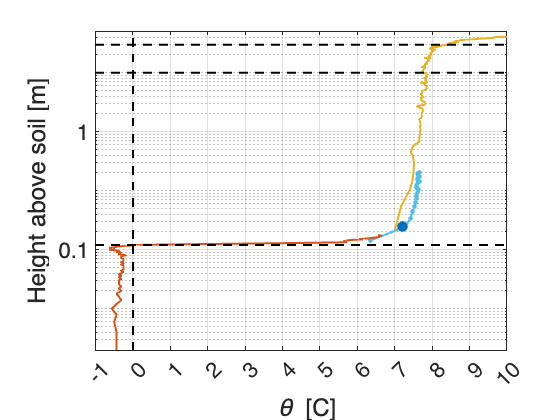

cmap = lines;
clf;

ti = tiledlayout(1,1);
ax1 = axes(ti);

toff = nanmean(theta_vaisala_30)-nanmean(theta_vaisala_50);

h1=plot(s_theta,s_ht,'linewidth',2,'color',cmap(3,:)); hold on;
h2=plot(nanmean(twr_theta(si,:)),[1:20]+sdoff,'k.-','linewidth',2,'color',cmap(6,:),'markersize',14);
h3=plot(ts_theta,ts.range,'linewidth',2,'color',cmap(2,:));

plot(nanmean(theta_vaisala_30),1.32+1.18,'ko','color',cmap(1,:),'markersize',10,'markerfacecolor',cmap(1,:));

set(gca,'yscale','log');
xlim([-1 10]); ylim([0.02 5000]);

ax=get(gca);
curtick = ax.YTick;
set(gca, 'YTickLabel', cellstr(num2str(curtick(:)))); 
xlabel('{\it \theta} [C]'); ylabel('Height above soil [m]');
hline(ts.range(rind(end)))
hline(c.first_cbh(ic))
vline(0)
hline(1000)
grid on; 
set(gca,'xtick',-2:11,'fontsize',22)

set(gcf,'PaperPositionMode','manual');
set(gcf,'PaperUnits','centimeters');
set(gcf,'PaperPosition',[0 0 30 30]);
print('-dpng','-r300',[figure_dir,'Figure_7orig.png']);